clear, clc, format short g


## PARTE 1

## 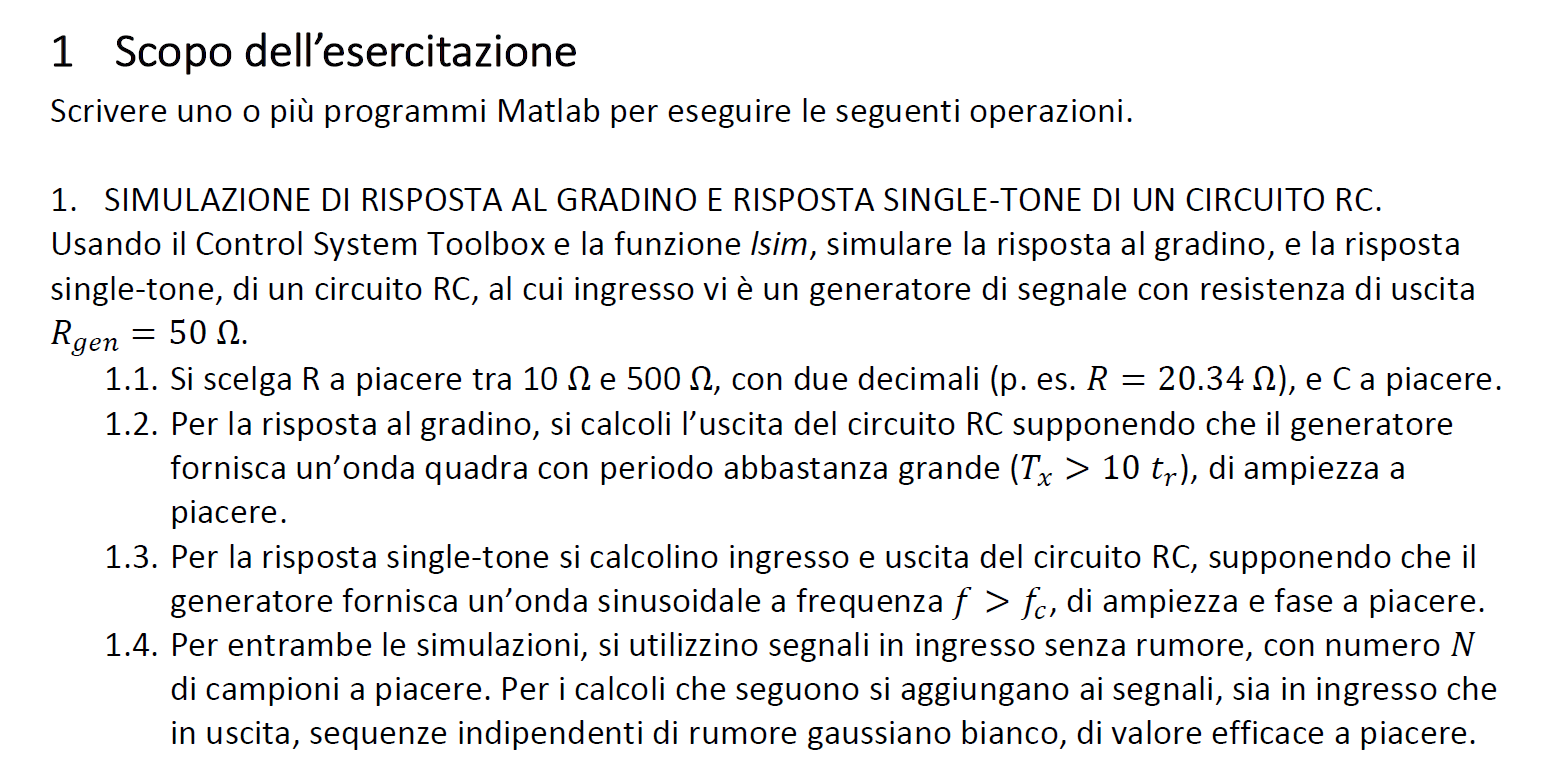


Rgen = 50;
R = 74.38;
C = 15e-9;


## definizione tau


tau_square = (R+Rgen)*C;
tau_sin = R*C

tau_sin =    1.1157e-06


## definizione periodi di campionamento

tr = tau_square * log(9)

tr =    4.0994e-06



Tx = 11*tr %periodo segnale

Tx =    4.5093e-05


Np = 3 % numero di periodi del segnale

Np =      3



Td = Tx*Np %durata simulazione

Td =    0.00013528



N = 1000;
n = (0:N-1)'; %indici dei campioni

Ts = Td/N %passo di campionamento

Ts =    1.3528e-07



t = n*Ts; %istanti di campionamento


## definizione onda quadra in ingresso

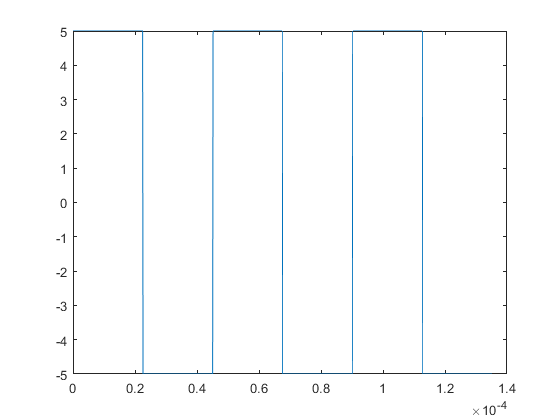

Vpp = 10;

x_square = Vpp/2*square(2*pi*t/Tx);

plot(t, x_square)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_square*s);


## definizione risposta al gradino

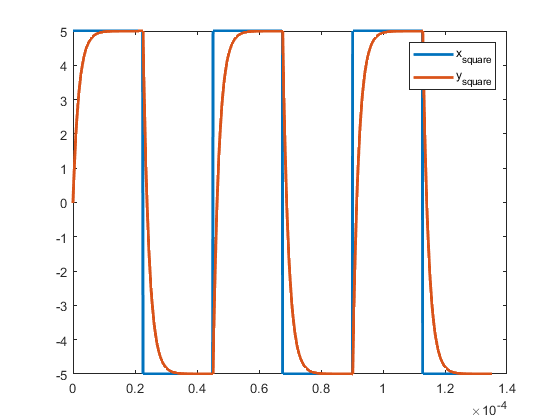

y_square = lsim(H1_dot, x_square, t);

plot(t, x_square, t, y_square, 'LineWidth', 2)

legend('x_{square}', 'y_{square}')

## definizione parametri sinusoide

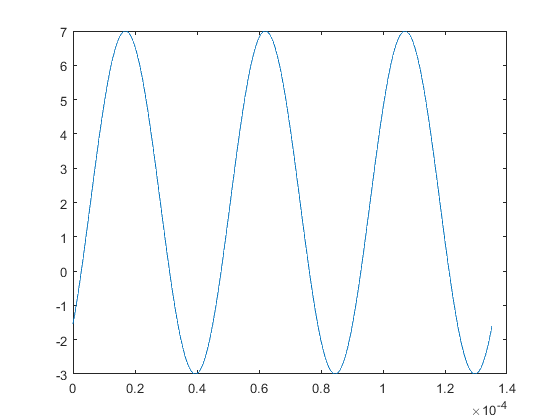

Np = 3;

fx = 1/Tx;

x_sin = 2 + Vpp/2*sin(2*pi*fx*t - pi/4);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

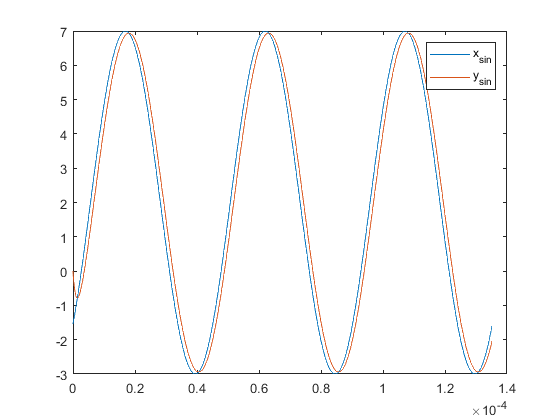

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

legend('x_{sin}', 'y_{sin}')

## aggiungo ai segnali in ingresso ed uscita rumore AWGN

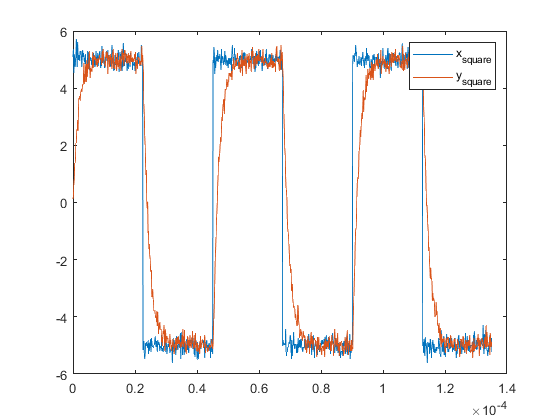

rng('default')
sigma = 0.2; %ampiezza del rumore
x_square = Vpp/2*square(2*pi*t/Tx) + randn(N,1)*sigma; % segnale in ingresso con rumore AWGN

y_square = lsim(H1_dot, x_square, t) + randn(N,1)*sigma; % segnale in uscita con rumore AWGN indipendente dall'ingresso

plot(t,x_square, t, y_square)

legend('x_{square}', 'y_{square}')

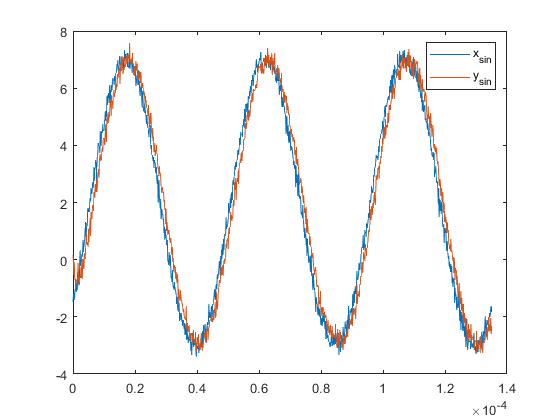


x_sin = 2 + Vpp/2*sin(2*pi*fx*t - pi/4) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)
legend('x_{sin}', 'y_{sin}')


save dati_punto_1 x_sin y_sin Tx Td N Np Ts n R Rgen C tau_sin t Vpp sigma H_dot fx